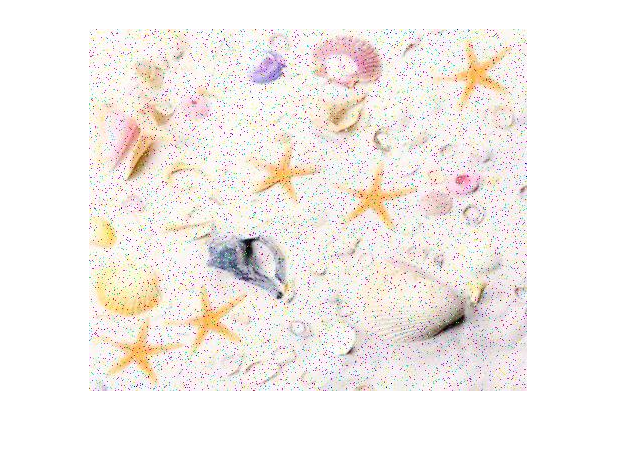

im = imread("images\starfish.jpg");
% im = rgb2hsv(im); 
imshow(im)

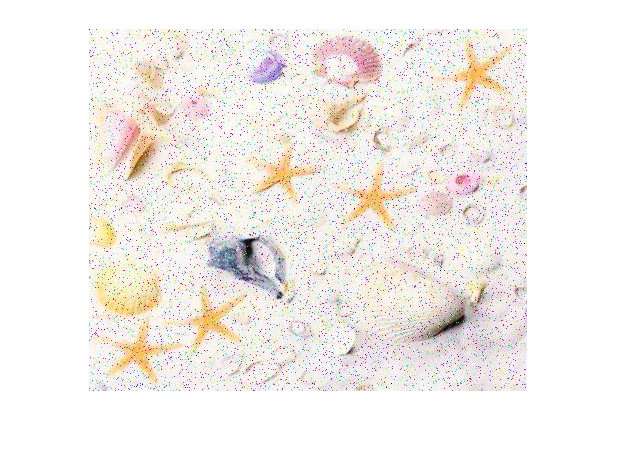

% DetectSnP(im)

im = DenoiseSP(im);
imshow(im)

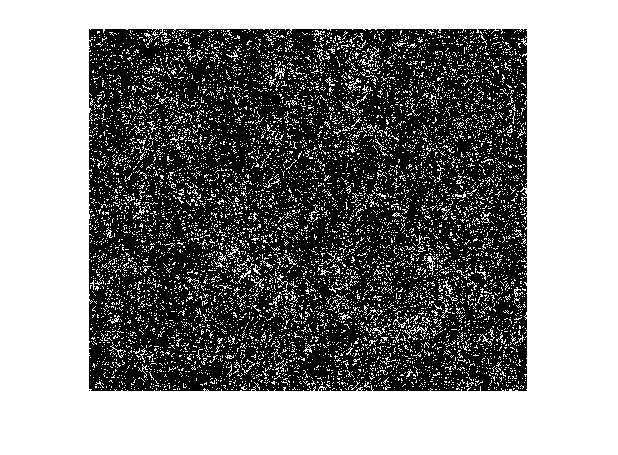

15.9491% noise



[c1,c2,c3] = imsplit(im);

% t= "wiener filter ";
% c1 = wiener2(c1);
% c2 = wiener2(c2);
% c3 = wiener2(c3);
% im = cat(3, c1,c2,c3);

t= "median filter ";
c1 = medfilt2(c1);
c2 = medfilt2(c2);
c3 = medfilt2(c3);
im = cat(3, c1,c2,c3);




[im, noise] = DenoiseIsolated(im);

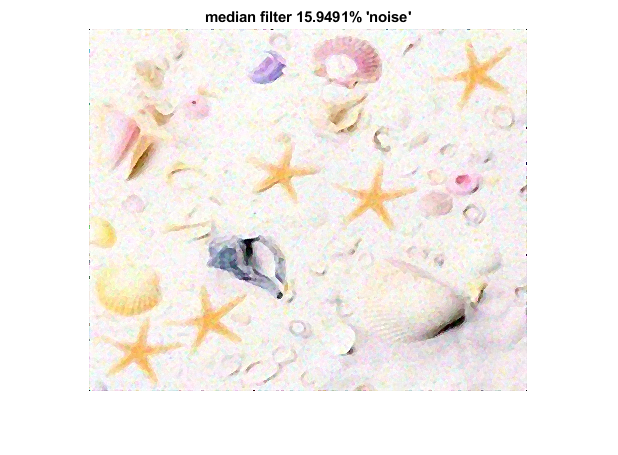


% t= "gaussian filter ";
% c1 = imgaussfilt(c1);
% c2 = imgaussfilt(c2);
% c3 = imgaussfilt(c3);
% im = cat(3, c1,c2,c3);
% 3

% filter = [-1 0 -1; 0 4 0; -1 0 -1]
% % filter = [0 -1 0; -1 4 -1; 0 -1 0]
% % filter = [-1 -1 -1; -1 8 -1; -1 -1 -1];
% [c1,c2,c3] = imsplit(im);
% c1 = conv2(double(c1), filter, 'same');
% c2 = conv2(double(c2), filter, 'same');
% c3 = conv2(double(c3), filter, 'same');
% im = cat(3, c1,c2,c3);

imshow(im);
title(t + noise + "% 'noise'");

function boolean = DetectSnP(im)
    imshow(im);
    theMean = mean(im(:))
    theStd = std2(im(:))
    histDetes = imhist(im);
    nPixels = numel(im)
    lowImpulse = histDetes(1)
    highImpulse = histDetes(255)
    impulseSum = lowImpulse+ highImpulse
    extremaPercentage = (100/nPixels) * impulseSum
    if (extremaPercentage > 100)
        disp("S&P DETECTED")
    end
end


function [ch1, ch2, ch3] = CountImpulsePixels(im)
[ch1, ch2, ch3] = imsplit(im);
ch1 = length(find(ch1 == 0 | ch1 == 255));
ch2 = length(find(ch2 == 0 | ch2 == 255));
ch3 = length(find(ch3 == 0 | ch3 == 255));
end
function imP = DenoiseSP(im)
dims = ndims(im);

if (dims == 2)
    imP = DenoiseSP2D(im);
elseif (dims == 3)
    imP = DenoiseSP3D(im);
else
    error("Unsupported number of dimensions. Expected a 2D or 3D array.");
end
% Little effect on low noise, tops off extra noisy ims.
% imP = imsharpen(imP);
% imP = medfilt3(imP);
% imP = imsharpen(imP);
end


function imP = DenoiseSP2D(im)
imP = im;
for i = 1:2 % Run twice
    noise = (imP == 0 | imP == 255);
    
    % Create a median filtered copy of im.
    filtered = medfilt2(imP, [3 3]);
    
    % Swap noisy pixels with filtered pixels.
    denoised = imP;
    denoised(noise) = filtered(noise);
    
    imP = denoised;
end

%     Consideration...
%     Conditionally determine filter size based on numel(noise).
end


function imP = DenoiseSP3D(im)
% Separate image channels.
[ch1, ch2, ch3] = imsplit(im);

% Denoise channels individually.
dnCh1 = DenoiseSP2D(ch1);
dnCh2 = DenoiseSP2D(ch2);
dnCh3 = DenoiseSP2D(ch3);

% Concatenate channels to create noise free image.
imP = cat(3, dnCh1, dnCh2, dnCh3);
end


function [imP, noisePercent] = DenoiseIsolated(im)
noiseThresh = 75;
dims = ndims(im);
noisePercent = 100;
if (dims == 2)
    while(noisePercent > noiseThresh)
        [im, noisePercent] = DenoiseIsolated2D(im);
    end
elseif (dims == 3)
    while(noisePercent > noiseThresh)
        [im, noisePercent] = DenoiseIsolated3D(im);
    end
else
    error("Unsupported number of dimensions. Expected a 2D or 3D array.");
end
    imP = im;
    disp(noisePercent + "% noise");
imP = imsharpen(imP, 'amount', 2);
end


function [imP, noisePercent] = DenoiseIsolated3D(im)
% Separate image channels.
[ch1, ch2, ch3] = imsplit(im);

% Denoise channels individually.
[dnCh1,noisePercent1] = DenoiseIsolated2D(ch1);
[dnCh2,noisePercent2] = DenoiseIsolated2D(ch2);
[dnCh3,noisePercent3] = DenoiseIsolated2D(ch3);

% Concatenate channels to create noise free image.
imP = cat(3, dnCh1, dnCh2, dnCh3);
noisePercent = mean([noisePercent1,noisePercent2,noisePercent3]);
end


function [imP, noisePercent] = DenoiseIsolated2D(im)
% Isolate speckle and S&P noise
% if s&p or isolated noise
filtered = medfilt2(im, [3 3]);
% if gaussian or speckle noise
% filtered = conv2(double(im), ones(3)/9, 'same');
imLnStd = log(std2(im));
diff = abs(double(im) - double(filtered));
noise = (diff > imLnStd);
imshow(noise)
noisyPixels = sum(noise(:));
nPx = numel(im);
noisePercent = (100/nPx) * noisyPixels;
noise = (noise == 1);

% Swap noisy pixels for filtered ones
imP = im;
imP(noise) = filtered(noise);
end
